clear
files = dir('angulos_recortados\*.csv');


for k = 1:length(files)

    T = readtable(fullfile('angulos_recortados',files(k).name));

    t = T.Time;

    %% Ángulos

    thetaC = calcAngles(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_a_0_X,...
        T.Angle1_a_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);

    thetaR = calcAngles(...
        T.Angle2_o_0_X,...
        T.Angle2_o_0_Y,...
        T.Angle2_a_0_X,...
        T.Angle2_a_0_Y,...
        T.Angle2_b_0_X,...
        T.Angle2_b_0_Y);

    thetaT = calcAnglesT(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);

    %% Corrección

    thetaR = 180 - thetaR;
    thetaT = 180 - thetaT;

    %% Segmentación

    [~,locs] = findpeaks(thetaC,...
        'MinPeakDistance',50,...
        'MinPeakProminence',10);

    cortes = [1 locs' length(thetaC)];

    nSeg = length(cortes)-1;

    segmentoC = cell(1,nSeg);
    segmentoR = cell(1,nSeg);
    segmentoT = cell(1,nSeg);
    segmentoTiempo = cell(1,nSeg);

    locsC = cell(1,nSeg);
    locsR = cell(1,nSeg);
    locsT = cell(1,nSeg);

    for i = 1:nSeg

        idx = cortes(i):cortes(i+1);

        segmentoC{i} = thetaC(idx);
        segmentoR{i} = thetaR(idx);
        segmentoT{i} = thetaT(idx);

        segmentoTiempo{i} = t(idx);

        [~,locsC{i}] = min(segmentoC{i});
        [~,locsR{i}] = max(segmentoR{i});
        [~,locsT{i}] = min(segmentoT{i});

    end

    %% Guardado

    data(k).archivo = files(k).name;

    data(k).t = t;

    data(k).cadera = thetaC;
    data(k).rodilla = thetaR;
    data(k).tronco = thetaT;

    data(k).segmentosC = segmentoC;
    data(k).segmentosR = segmentoR;
    data(k).segmentosT = segmentoT;

    data(k).segmentosTiempo = segmentoTiempo;

    data(k).locsC = locsC;
    data(k).locsR = locsR;
    data(k).locsT = locsT;

end


%% Crear participantes

Participante(1).nombre = "P1";
Participante(1).series = data(1:5);
Participante(1).seriesAnalizar = [2,3,5];

Participante(2).nombre = "P2";
Participante(2).series = data(6:10);
Participante(2).seriesAnalizar = [2,4,5];

for p = 1:length(Participante)

    for s = Participante(p).seriesAnalizar

        serie = Participante(p).series(s);
        nRep = min(3,length(serie.segmentosC));

        for r = 1:length(serie.segmentosC)

            thetaC = serie.segmentosC{r};
            thetaR = serie.segmentosR{r};
            thetaT = serie.segmentosT{r};

            tRep = serie.segmentosTiempo{r};

            idxPMF = serie.locsC{r};

            rep = struct();

            rep.numRep = r;

            rep.thetaC_PI  = thetaC(1);
            rep.thetaC_PMF = thetaC(idxPMF);
            rep.thetaC_PF  = thetaC(end);

            rep.thetaR_PI  = thetaR(1);
            rep.thetaR_PMF = thetaR(idxPMF);
            rep.thetaR_PF  = thetaR(end);

            rep.thetaT_PI  = thetaT(1);
            rep.thetaT_PMF = thetaT(idxPMF);
            rep.thetaT_PF  = thetaT(end);

            rep.ROM_C = calcROM(thetaC);
            rep.ROM_R = calcROM(thetaR);
            rep.ROM_T = calcROM(thetaT);

            [rep.texc,rep.tcon] = calcPhases(tRep,idxPMF);

            rep.ttot = calcDuration(tRep);

            Participante(p).series(s).rep(r) = rep;

        end

    end

end

% Estadistica
campos = {
'thetaC_PI','thetaC_PMF','thetaC_PF',...
'thetaR_PI','thetaR_PMF','thetaR_PF',...
'thetaT_PI','thetaT_PMF','thetaT_PF',...
'ROM_C','ROM_R','ROM_T',...
'texc','tcon','ttot'};
for p = 1:length(Participante)

    for c = 1:length(campos)

        campo = campos{c};
        valores = [];

        for s = Participante(p).seriesAnalizar

            serie = Participante(p).series(s);

            for r = 1:length(serie.rep)

                valores(end+1) = serie.rep(r).(campo);

            end
        end

        Participante(p).stats.(campo) = calcStats(valores);

    end

end

campos = fieldnames(Participante(1).stats);

for c = 1:length(campos)

    campo = campos{c};

    Resultados.tabla(c).Variable = campo;

    Resultados.tabla(c).P1_mean = ...
        Participante(1).stats.(campo).mean;

    Resultados.tabla(c).P1_std = ...
        Participante(1).stats.(campo).std;

    Resultados.tabla(c).P2_mean = ...
        Participante(2).stats.(campo).mean;

    Resultados.tabla(c).P2_std = ...
        Participante(2).stats.(campo).std;

    Resultados.tabla(c).DiffAbs = abs( ...
        Participante(1).stats.(campo).mean - ...
        Participante(2).stats.(campo).mean );

end
struct2table(Resultados.tabla)

ans = 15×6 table
       Variable       P1_mean    P1_std     P2_mean    P2_std      DiffAbs 
    ______________    _______    _______    _______    _______    _________

    {'thetaC_PI' }    173.08      2.9422    179.15      3.6088       6.0638
    {'thetaC_PMF'}    38.264      6.1832    63.686      3.8148       25.423
    {'thetaC_PF' }    171.83      3.1191    180.54      3.4901       8.7067
    {'thetaR_PI' }    15.325      2.4858    9.3976       2.577       5.9272
    {'thetaR_PMF'}    30.708      5.9788    26.375      3.6674       4.3336
    {'thetaR_PF' }    15.104      2.7201    8.5806       2.524       6.5235
    {'thetaT_PI' }    179.02      1.6202    182.36      3.0208       3.3328
    {'thetaT_PMF'}    66.591       4.639    90.888      2.8211       24.296
    {'thetaT_PF' }

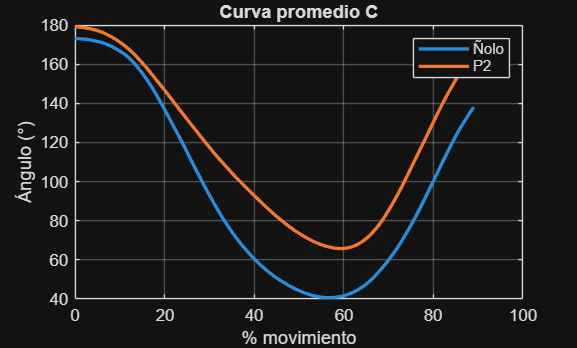


%% Curvas normalizadas

senales = {'C','R','T'};

for p = 1:length(Participante)

    for ss = 1:length(senales)

        senal = senales{ss};

        segmentosTotales = {};
        tiemposTotales = {};

        for s = Participante(p).seriesAnalizar

            serie = Participante(p).series(s);

            switch senal

                case 'C'
                    segmentos = serie.segmentosC;

                case 'R'
                    segmentos = serie.segmentosR;

                case 'T'
                    segmentos = serie.segmentosT;

            end

            segmentosTotales = ...
                [segmentosTotales segmentos];

            tiemposTotales = ...
                [tiemposTotales serie.segmentosTiempo];

        end

        Participante(p).curvas.(senal).segmentos = ...
            segmentosTotales;

        Participante(p).curvas.(senal).tiempo = ...
            tiemposTotales;

    end

end

senales = {'C','R','T'};

for p = 1:length(Participante)

    for ss = 1:length(senales)

        senal = senales{ss};

        [curvas,~] = normalizeTime( ...
            Participante(p).curvas.(senal).segmentos,...
            Participante(p).curvas.(senal).tiempo);

        Participante(p).curvas.(senal).data = curvas;
        Participante(p).curvas.(senal).mean = mean(curvas,1);
        Participante(p).curvas.(senal).std  = std(curvas,[],1);

    end

end
senales = {'C','R','T'};

for ss = 1:length(senales)

    senal = senales{ss};

    figure

    plot(0:100,...
        Participante(1).curvas.(senal).mean,...
        'LineWidth',2)

    hold on

    plot(0:100,...
        Participante(2).curvas.(senal).mean,...
        'LineWidth',2)

    title(['Curva promedio ' senal])
    xlabel('% movimiento')
    ylabel('Ángulo (°)')
    legend('Ñolo','P2')
    grid on

end


figure('Position',[50 50 1400 800])

%% P1

subplot(3,3,1)

plotMeanStdTime(...
    Participante(1).curvas.C.segmentos,...
    Participante(1).curvas.C.tiempo,...
    'P1 - Cadera')

subplot(3,3,2)

plotMeanStdTime(...
    Participante(1).curvas.T.segmentos,...
    Participante(1).curvas.T.tiempo,...
    'P1 - Tronco')

subplot(3,3,3)

plotMeanStdTime(...
    Participante(1).curvas.R.segmentos,...
    Participante(1).curvas.R.tiempo,...
    'P1 - Rodilla')

%% P2

subplot(3,3,4)

plotMeanStdTime(...
    Participante(2).curvas.C.segmentos,...
    Participante(2).curvas.C.tiempo,...
    'P2 - Cadera')

subplot(3,3,5)

plotMeanStdTime(...
    Participante(2).curvas.T.segmentos,...
    Participante(2).curvas.T.tiempo,...
    'P2 - Tronco')

subplot(3,3,6)

plotMeanStdTime(...
    Participante(2).curvas.R.segmentos,...
    Participante(2).curvas.R.tiempo,...
    'P2 - Rodilla')










% Funciones
function theta = calcAngles(Ox, Oy, Ax, Ay, Bx, By)

    OAx = Ax - Ox;
    OAy = Ay - Oy;

    OBx = Bx - Ox;
    OBy = By - Oy;

    dotprod = OAx.*OBx + OAy.*OBy;
    crossprod = OAx.*OBy - OAy.*OBx;

    theta = atan2d(crossprod, dotprod);

    theta(theta < 0) = theta(theta < 0) + 360;

end
function theta = calcAnglesT(Ox, Oy, Ax, Ay)

    OAx = Ax - Ox;
    OAy = Ay - Oy;
    
    theta = atan2d(OAx, OAy);
end
% Funciones para calcular variables individuales
function rom = calcROM(theta)

    rom = max(theta) - min(theta);

end
function dur = calcDuration(t)

    dur = t(end) - t(1);

end
% idxMax son los locs de rodilla o tronco
function [tEcc,tCon] = calcPhases(t,idxMax) 

    tEcc = t(idxMax) - t(1);

    tCon = t(end) - t(idxMax);

end

% Funciones para analizar estadistica
function S = calcStats(x)

    S.data = x;
    S.mean = mean(x);
    S.std  = std(x);
    S.min  = min(x);
    S.max  = max(x);
    S.rng  = max(x) - min(x);

end

% Funcion para normalizar
function curvasNorm = normalizeReps(segmentos)

    xq = linspace(0,100,101);

    nRep = length(segmentos);

    curvasNorm = zeros(nRep,101);

    for r = 1:nRep

        theta = segmentos{r};

        x = linspace(0,100,length(theta));

        curvasNorm(r,:) = interp1(x,theta,xq);

    end

end

function [curvas,tNorm] = normalizeTime(segmentos,segmentosTiempo)

    duraciones = zeros(1,length(segmentos));

    for r = 1:length(segmentos)

        tRep = segmentosTiempo{r};
        duraciones(r) = tRep(end)-tRep(1);

    end

    tMean = mean(duraciones);

    tNorm = linspace(0,tMean,101);

    curvas = zeros(length(segmentos),101);

    for r = 1:length(segmentos)

        theta = segmentos{r};

        tRep = segmentosTiempo{r};
        tRep = tRep - tRep(1);

        curvas(r,:) = interp1( ...
            tRep,...
            theta,...
            tNorm,...
            'linear');

    end

end

function plotMeanStdTime(segmentos,segmentosTiempo,titulo)

    [curvas,tNorm] = ...
        normalizeTime(segmentos,segmentosTiempo);

    mu = mean(curvas,1);
    sigma = std(curvas,[],1);

    hold on

    fill( ...
        [tNorm fliplr(tNorm)],...
        [mu+sigma fliplr(mu-sigma)],...
        [0.85 0.85 0.85],...
        'EdgeColor','none',...
        'FaceAlpha',0.5);

    plot(tNorm,...
        curvas',...
        'Color',[0.7 0.7 0.7]);

    plot(tNorm,...
        mu,...
        'k',...
        'LineWidth',2);

    xlabel('Tiempo normalizado (s)')
    ylabel('Ángulo (°)')
    title(titulo)

    grid on

end